## Metabolic Modelling Introduction 

Authors : Vanille Lejal, Hugues Escoffier & Maria Pires Pacheco

% Choosing the solver
changeCobraSolver('ibm_cplex');
% changeCobraSolver('gurobi');

#### Creation of a Toy Model

**Model : **

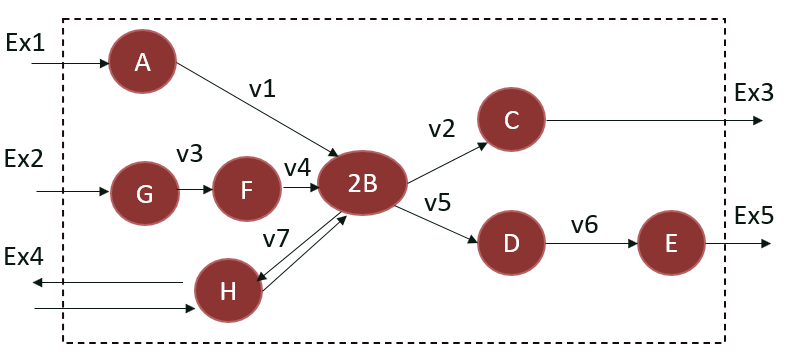

There are several ways to implement a model. The main difference between writing conventions concerns exchange reactions, particularly import reactions. One approach, referred to as "classical" here, uses double-arrows (<=>) for exchange reactions that allow both import and export (e.g. Ex4) and simple arows (->) for exchange reactions that permit only import (e.g. Ex2). Below is the complete implementation of the model represented above:

clear

%Create Model
ReactionFormulasClassical = {'A -> 2 B','2 B -> C', 'G -> F','F -> 2 B', '2 B -> D','D -> E', ...
                    'H <=> 2 B', '-> A', '-> G', 'C ->', '<=> H', 'E ->'};
ReactionNamesClassical = {'v1','v2','v3', 'v4', 'v5', 'v6', 'v7', 'Ex1','Ex2','Ex3','Ex4','Ex5'};
GeneNamesClassical = {'Gene1','Gene2','Gene3', 'Gene4', 'Gene5', 'Gene6','Gene7','GeneEx1', 'GeneEx2', 'GeneEx3', 'GeneEx4', 'GeneEx5'};
model_classical = createModel(ReactionNamesClassical, ReactionNamesClassical, ReactionFormulasClassical,'grRuleList',GeneNamesClassical);
model_classical.description = 'classical'
disp('mets'); model_classical.mets
disp('genes'); model_classical.genes
printRxnFormula(model_classical);

If you look at the stoichiometric matrix, you can see that export reactions have negative coefficients, while both import and reversible reactions have positive coefficients.

disp('S'); full(model_classical.S)

Irreversible reactions (both import and export) have bounds set between 0 and 1000. Reversible exchange reactions have bounds set between -1000 and 1000.

disp('boundaries'); disp([model_classical.rxns num2cell(model_classical.lb) num2cell(model_classical.ub)])

**However, in metabolic modelling, we generally follow the convention used in the Recon 3D model. In the Recon convention, all import reactions are defined as exports and reversible. **

For example, in this model the import reaction ' -> G', becomes by convention a reversible exchange reaction written 'G <=>'. Below is the complete implementation of the above model using the Recon convention:

%Create Model as Recon3D
ReactionFormulasRecon = {'A -> 2 B', '2 B -> C', 'G -> F','F -> 2 B', '2 B -> D','D -> E', ...
                    'H <=> 2 B', 'A <=>', 'G <=>', 'C ->', 'H <=>', 'E ->'};
ReactionNamesRecon = {'v1', 'v2','v3', 'v4', 'v5', 'v6', 'v7', 'Ex1','Ex2','Ex3','Ex4','Ex5'};
GeneNamesRecon = {'Gene1', 'Gene2','Gene3', 'Gene4', 'Gene5', 'Gene6','Gene7','GeneEx1', 'GeneEx2', 'GeneEx3', 'GeneEx4', 'GeneEx5'};
model_recon = createModel(ReactionNamesRecon, ReactionNamesRecon, ReactionFormulasRecon,'grRuleList',GeneNamesRecon);
model_recon.description = 'recon';
disp('mets') ; model_recon.mets %Metabolites 
disp('genes') ; disp(model_recon.genes)
printRxnFormula(model_recon)

With the Recon convention, all exchange reactions have negative coefficients in the stoichiometric matrix. Indeed, import reactions are written as reversible export reaction.

disp('S') ; full(model_recon.S) %S Matrix

As with the "classical" convention, export reactions have a lower bound of 0 and an upper bound of 1000 (e.g. Ex3). However, since import reactions are written as reversible export reactions, they have negative coefficients in the stoichiometric matrix S, and have lower bounds set to -1000 and upper bounds set to 1000 (e.g. Ex1).

disp('boundaries') ; disp([model_recon.rxns num2cell(model_recon.lb) num2cell(model_recon.ub)]) %Upper & Lower boundaries for each reactions

#### Model Consistency Verification

Model consistency means that each reaction is capable of carrying a non-zero flux. This is achieved by eliminating dead-ends and gaps, or by gap filling.

Let's verify the consistency of the model:

A_recon = fastcc(model_recon, 1e-4, 2); % A contains the indexes of reactions kept in the consistent model
A_classical = fastcc(model_classical, 1e-4, 2);

As you can see, both models are consistent regardless of the convention.

% in case you face an inconsistent model, you can make it consistent by removing the non consistent reactions from it.
%consistent_model = removeRxns(model, model.rxns(setdiff(1:numel(model.rxns), A)))

#### Exchange Reactions and Medium Constraints

Exchange reactions are reactions that link the system to the extracellular environment represented by the reactions leaving the recangle in the toy model. 

To match reality, we want the model to be able to exchange only with the metabolites present in the medium (metabolite A in this example).

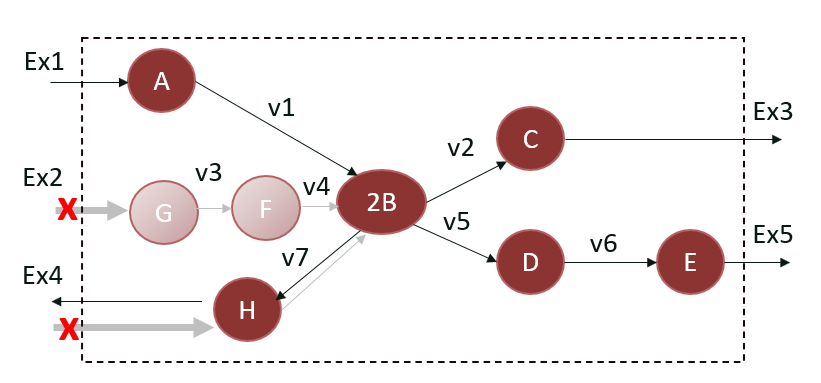

medium = {'A[c]'} % Create the medium containing only the metabolite 'A[c]'
[EX] = findExcRxns(model_recon); % Find all exchange reactions
printRxnFormula(model_recon, model_recon.rxns(EX)); % Shows all exchange reactions
[Ex_open] = findRxnsFromMets(model_recon, medium) % Shows reactions that involve metabolites of the medium
Ex_to_close = setdiff(model_recon.rxns(EX), Ex_open) % Find the reactions that should be unable to carry a flux based on the medium composition

As explained in the previous section, to contrain a model based on the medium composition, we have to close certain exchange reactions, notably the import reactions. In practice, this means setting the bounds of the relevant reactions to zero. However, depending on the writing convention chosen to encode the model, the bounds of the import reactions differ, and consequently the method for closing them are not be the same.

**For the 'classical' model **

medium_model_classical = model_classical; % Save in case of mistake

for i = 1:length(Ex_to_close) % For each reactions to close
    % We only want to close the import reactions, so we search for them in the stoichimetric matrix 
    var = nonzeros(medium_model_classical.S(:,ismember(medium_model_classical.rxns,Ex_to_close(i)))); % Return +1 if the reaction is an import / -1 if it is an export
     if var > 0 % Import reactions
         medium_model_classical.ub(ismember(medium_model_classical.rxns,Ex_to_close(i))) = 0; % Close the upper bound (cannot receive a flux anymore)
     end
end

disp('boundaries') ; disp([medium_model_classical.rxns num2cell(medium_model_classical.lb) num2cell(medium_model_classical.ub)]) % New Upper boundaries for exchange reactions

Ex1 is the only import reaction allowed, the bounds did not change. Ex2 and Ex4 have their upper bounds set to 0, they can not import metabolites anymore.

**For the Recon3D-like model**

All import reactions are defined as reversible export reactions, so a flux through an import reaction corresponds to a negative flux. Thus, import reactions are blocked by setting the lower bound of each of these reactions to zero.

medium_model_recon = model_recon; % Save in case of mistake
medium_model_recon.lb(ismember(medium_model_recon.rxns, Ex_to_close)) = 0
disp('boundaries') ; disp([medium_model_recon.rxns num2cell(medium_model_recon.lb) num2cell(medium_model_recon.ub)])

Ex2 and Ex4 have their lower bounds set to 0. They can not import metabolites anymore.

Both "classical" and "Recon" models are valid. However, as the Recon convention is the most commonly used in metabolic modelling, we will now only use this one and the corresponding model.

Once we constrained the model based on the medium composition, we need to check that the model is still consistent.

% Create a consistent model constrained by the metabolites present in the model 
A_recon_2 = fastcc(medium_model_recon, 1e-4, 2) % List of the consistent reactions of the model.

Now that we close some exchange reactions, the model is not consistent anymore. We need to remove the reactions that are not supported anymore. We will create a new medium constrained consistent model with only the remaining consistent reactions.

medium_constrained_consistent_model = removeRxns(medium_model_recon, medium_model_recon.rxns(setdiff(1:numel(medium_model_recon.rxns), A_recon_2)));

disp('mets') ; medium_constrained_consistent_model.mets %Metabolites 

v3, v4 and Ex2 were not consistent anymore, so they have been removed from the model.

disp('rxns') ; medium_constrained_consistent_model.rxns %Reactions

Please notice that we are only removing the reactions, all the genes are still present in the model:

disp('genes') ; medium_constrained_consistent_model.genes %Genes

**Consistent model after adding the condition on the medium : **

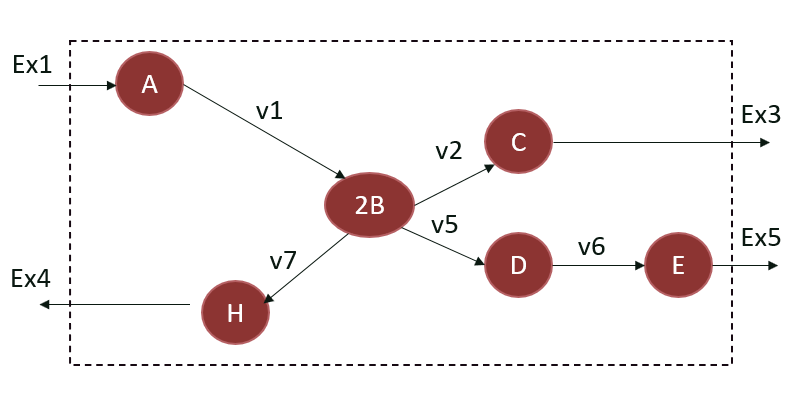

#### Introduction to rFastcormics : Integration of core reactions

Context-specific models contain only reactions active in the context of interest. Different context-specif algorithms exist. **Fastcore **algorithm uses a set of core reactions that is guaranteed to be active in the extracted model and finds the minimum of reactions possible to support the core. **rFastcormics **uses RNA-Seq data to determine the reactions that can be active based on gene expression values,* i.e.* core reactions.

• **Core reactions** correspond to reactions supported by the data (active genes). Core reactions are forced to carry a flux above epsilon (small positive value) by an approximation of the cardinality function. 

• **Inactive reactions **correspond to reactions that are not supported by the data (inactive genes) and that can not carry a flux.

• **Non Core reactions **correspond to reactions relying on genes that are expressed but not enough to be considered active. The inclusion of non core reactions is minimized by a L1-regularization: the inclusion on non-core reactions is penalized so that only non core reactions that are required to allow core reactions to be consistent are included).

Let's see with an example (schema below). Based on gene expression data, we got:

- Core reactions (*forced to carry a flux*) : **Ex3, v7**

- Inactive reaction (*do not carry a flux*) :  **v2. **

- Non core reactions :** others.**

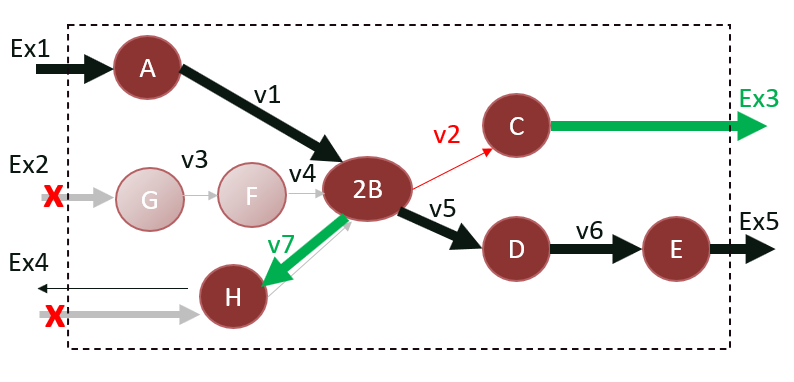

**Here is how to use rFastcormics in MATLAB: **

fastcormics_RNAseq(model, data, rownames, dico, biomass_rxn, already_mapped_tag, consensus_proportion, epsilon, optinal_settings)

- **model **: Model use to extract the context-specific model from.

- **data** : Matrix with *n* rows (1 per rxns) and *m* columns (1 per sample) with 1 for expressed genes, 0 for unknown expression and -1 for unexpressed genes. 

- **rownames** : The gene names for each row in the data.

- **dico** :  Dictionary to map the gene names to the gene names in the model (e.g. Entrez to EnsemblID).

- **biomass_rxn **: Rxn that is (*generally*) to be maximized

- **already_mapped_tag** :  0 if the data has not been mapped to the GPR rules of the model, 1 otherwise

- **consensus_proportion** : In the case where several samples are used to reconstruct a model.

- **epsilon** : Flux threshold value (1e-4).

- **optional_settings **: Structure containing 4 elements (see below).

**optional_settings : **

- **unpenalized** : Matrix containing the rxns that should not be penalized during model creation. These reactions are chosen above the others, even though they are not part of the core reactions. Generally include transport reactions.

- **func** : Rxns that are (*generally*) to be maximized and must be retained (biomassReactionName should be included).

- **not_medium_constrained** : Rxns not included in the medium that must be retained.

- **medium** : Metabolites present in the medium (*rFastcormics can be used to constrain the model based on the medium).*

% For this model, we create a discretized matrix based on the information in the description: 
% -1 for inactive reactions (non-expressed genes), 1 for core reactions (expressed genes), 0 for non-core reactions.
data = [0;-1;0;0;0;0;1;0;0;1;0;0];

rownames = medium_constrained_consistent_model.genes;
dico = table(medium_constrained_consistent_model.genes, medium_constrained_consistent_model.genes);
biomass_rxn = 'Ex5'; % In this example we want to maximize 'Ex5'
already_mapped_tag = 0; 
consensus_proportion = 1; % Here we have only one sample
epsilon = 1e-4;

% Optional settings 
optional_settings = struct;
optional_settings.unpenalized = {};
optional_settings.func = {'Ex5'};
%optional_settings.medium = {}; % Here, we already have a medium constrained consistent model
%optional_settings.not_medium_constrained = {};

#### Creation of the 'Medium & Core Constrained Consistent Model' 

To create a model from the A_final array, we will create a logical matrix with the samples as columns and the reactions as rows in which 1 depicts if a reaction should take place in the context-specific model.

% run fastcormics_RNAseq
[medium_core_constrained_consistent_model, A_final] = fastcormics_RNAseq(medium_constrained_consistent_model, data, rownames, dico, biomass_rxn, already_mapped_tag, consensus_proportion, epsilon, optional_settings)

**Medium & Core Constrained Consistent Model : **

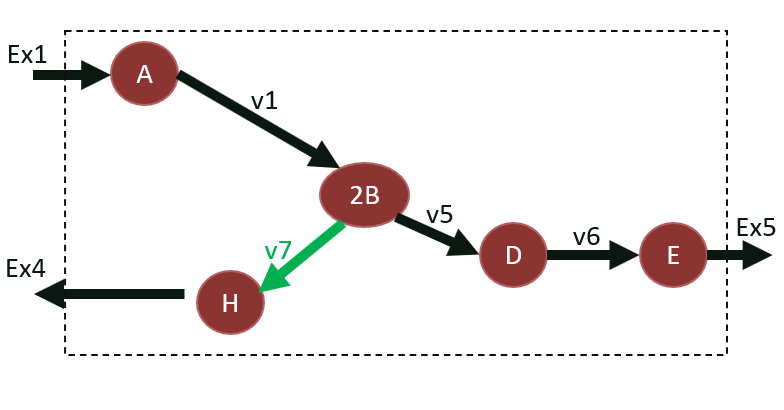

Ex1 and v1 were conserved due to the composition of the medium. Even though Ex3 for a core reaction, it was removed from the model. Indeed, Ex3 is supposed to be supported by v2, which was known to be inactive. Ex4 was retained due to the activity of v7. Finally, since Ex5 was maximized, v5 and v6 (both non core reactions) were preserved even though their inclusion in the model were penalized.

disp('mets') ; medium_core_constrained_consistent_model.mets %Metabolites 
disp('rxns') ; medium_core_constrained_consistent_model.rxns %Reactions

#### Objective and optimisation of the Model

We set an objective function in the model. In this example we have decided to maximize the rxn 'Ex5'.

index_objective_rxn = find(ismember(medium_core_constrained_consistent_model.rxns, 'Ex5')); % Find the index of the 'Ex5' rxn
medium_core_constrained_consistent_model = changeObjective(medium_core_constrained_consistent_model, medium_core_constrained_consistent_model.rxns(index_objective_rxn)); % Change the objective function 
printObjective(medium_core_constrained_consistent_model) % Check the change has been done

We can now optimize the model to get the maximal value through the 'v5' rxn.

solution = optimizeCbModel(medium_core_constrained_consistent_model,'max')
disp(solution.f)

The solution.f field give the maximal value of the flux through the objective function. 